# Laborator 4

## Problema 1

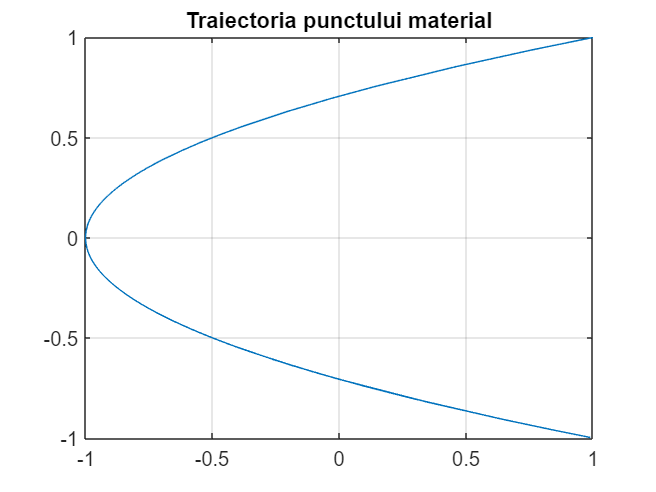

syms x(t) y(t);

x_0=1;
dx_0=0;
f=-4.*x;
a=0;
b=5;

Dx=diff(x);
x_eq=diff(x,t,2)==f;
x_cond=x(a)==x_0;
Dx_cond=Dx(a)==dx_0;
x_conds=[x_cond Dx_cond];
x_sol(t)=dsolve(x_eq,x_conds);

x=matlabFunction(x_sol);

y_0=1;
dy_0=0;
g=-y;

Dy=diff(y);
y_eq=diff(y,t,2)==g;
y_cond=y(a)==y_0;
Dy_cond=Dy(a)==dy_0;
y_conds=[y_cond Dy_cond];
y_sol(t)=dsolve(y_eq,y_conds);

y=matlabFunction(y_sol);

fplot(x,y,[a,b])
grid on
title("Traiectoria punctului material")

## Problema 2

### a) $M_0 \left(0,0\right),\alpha =\frac{\pi }{3},v_0 =8$

syms x(t) y(t);

v_0=8;
alfa=pi/3;
x_0=0;
dx_0=v_0.*cos(alfa);
f=0;
t_0=0;

Dx=diff(x);
x_eq=diff(x,t,2)==f;
x_cond=x(t_0)==x_0;
Dx_cond=Dx(t_0)==dx_0;
x_conds=[x_cond Dx_cond];
x_sol(t)=dsolve(x_eq,x_conds);

x=matlabFunction(x_sol);

g=9.8;
y_0=0;
dy_0=v_0.*sin(alfa);
f1=-g;

Dy=diff(y);
y_eq=diff(y,t,2)==f1;
y_cond=y(t_0)==y_0;
Dy_cond=Dy(t_0)==dy_0;
y_conds=[y_cond Dy_cond];
y_sol(t)=dsolve(y_eq,y_conds);

y=matlabFunction(y_sol);

v_x=diff(x_sol);
v_y=diff(y_sol);
v=sqrt(v_x.^2+v_y.^2);
eq=y(t)==0;
assume(t>0)
t_f=solve(eq);
d=x(t_f)-x_0

$$d = \frac{160\,\sqrt{3}}{49}$$

h_max=t_f

$$h\_max = \frac{40\,\sqrt{3}}{49}$$

v_f=v(t_f)

$$v\_f = 8$$

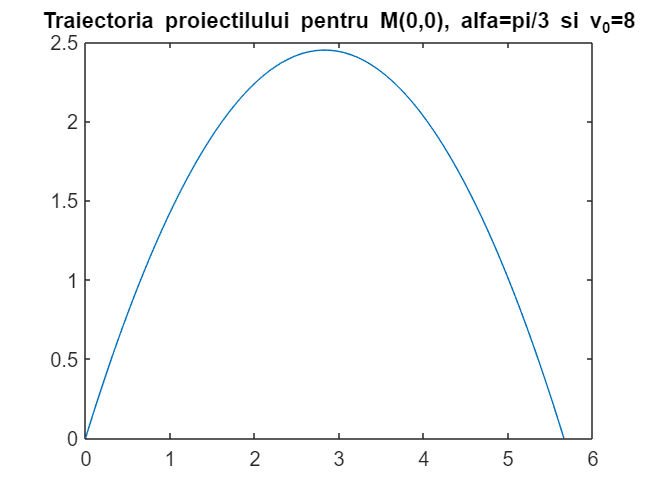

t=linspace(t_0,t_f);

plot(x(t),y(t))
title("Traiectoria proiectilului pentru M(0,0), alfa=pi/3 si v_0=8")

### b) $M_0 \left(0,10\right),\alpha =\frac{\pi }{4},v_0 =15$

syms x(t) y(t)

v_0=15;
alfa=pi/4;
x_0=0;
dx_0=v_0.*cos(alfa);
f=0;
t_0=0;

Dx=diff(x);
x_eq=diff(x,t,2)==f;
x_cond=x(t_0)==x_0;
Dx_cond=Dx(t_0)==dx_0;
x_conds=[x_cond Dx_cond];
x_sol(t)=dsolve(x_eq,x_conds);

x=matlabFunction(x_sol);

g=9.8;
y_0=10;
dy_0=v_0.*sin(alfa);
f1=-g;

Dy=diff(y);
y_eq=diff(y,t,2)==f1;
y_cond=y(a)==y_0;
Dy_cond=Dy(a)==dy_0;
y_conds=[y_cond Dy_cond];
y_sol(t)=dsolve(y_eq,y_conds);

y=matlabFunction(y_sol);

v_x=diff(x_sol);
v_y=diff(y_sol);
v=sqrt(v_x.^2+v_y.^2);
eq=y(t)==0;
assume(t>0)
t_f=solve(eq);
d=x(t_f)-x_0

$$d = \frac{15\,\sqrt{2}\,\left(\frac{5\,\sqrt{2}\,\sqrt{617}}{98}+\frac{75\,\sqrt{2}}{98}\right)}{2}$$

h_max=t_f

$$h\_max = \frac{5\,\sqrt{2}\,\sqrt{617}}{98}+\frac{75\,\sqrt{2}}{98}$$

v_f=v(t_f)

$$v\_f = \sqrt{421}$$

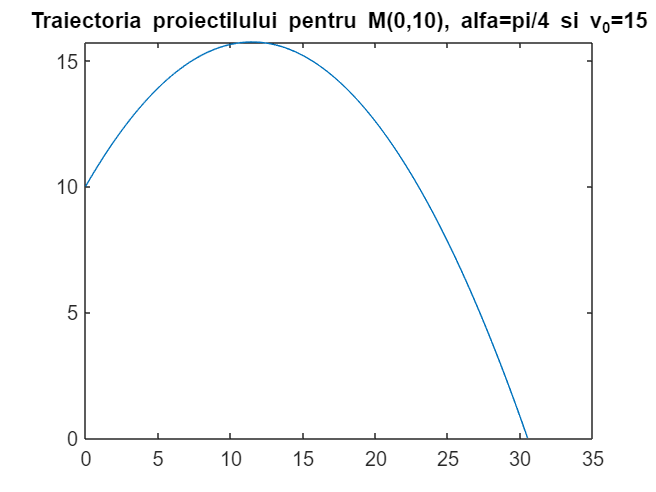

t=linspace(t_0,t_f);

plot(x(t),y(t))
title("Traiectoria proiectilului pentru M(0,10), alfa=pi/4 si v_0=15")

### c) $M_0 \left(0,40\right),\alpha =0,v_0 =5$

syms x(t) y(t)

v_0=5;
alfa=0;
x_0=0;
dx_0=v_0.*cos(alfa);
f=0;
t_0=0;

Dx=diff(x);
x_eq=diff(x,t,2)==f;
x_cond=x(t_0)==x_0;
Dx_cond=Dx(t_0)==dx_0;
x_conds=[x_cond Dx_cond];
x_sol(t)=dsolve(x_eq,x_conds);

x=matlabFunction(x_sol);

g=9.8;
y_0=40;
dy_0=v_0.*sin(alfa);
f1=-g;

Dy=diff(y);
y_eq=diff(y,t,2)==f1;
y_cond=y(a)==y_0;
Dy_cond=Dy(a)==dy_0;
y_conds=[y_cond Dy_cond];
y_sol(t)=dsolve(y_eq,y_conds);

y=matlabFunction(y_sol);

v_x=diff(x_sol);
v_y=diff(y_sol);
v=sqrt(v_x.^2+v_y.^2);
eq=y(t)==0;
assume(t>0)
t_f=solve(eq);
d=x(t_f)-x_0

$$d = \frac{100}{7}$$

h_max=t_f

$$h\_max = \frac{20}{7}$$

v_f=v(t_f)

$$v\_f = \sqrt{809}$$

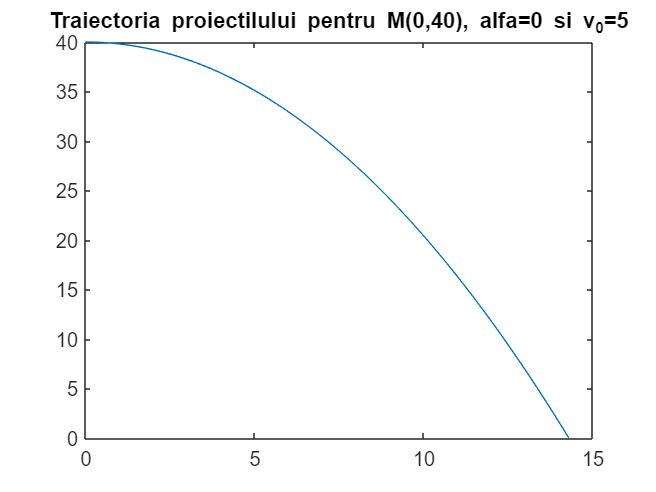

t=linspace(t_0,t_f);

plot(x(t),y(t))
title("Traiectoria proiectilului pentru M(0,40), alfa=0 si v_0=5")

### d) $M_0 \left(10,30\right),\alpha =\frac{\pi }{2},v_0 =3$

syms x(t) y(t)

v_0=3;
alfa=pi/2;
x_0=10;
dx_0=v_0.*cos(alfa);
f=0;
t_0=0;

Dx=diff(x);
x_eq=diff(x,t,2)==f;
x_cond=x(t_0)==x_0;
Dx_cond=Dx(t_0)==dx_0;
x_conds=[x_cond Dx_cond];
x_sol(t)=dsolve(x_eq,x_conds);

x=matlabFunction(x_sol);

g=9.8;
y_0=30;
dy_0=v_0.*sin(alfa);
f1=-g;

Dy=diff(y);
y_eq=diff(y,t,2)==f1;
y_cond=y(a)==y_0;
Dy_cond=Dy(a)==dy_0;
y_conds=[y_cond Dy_cond];
y_sol(t)=dsolve(y_eq,y_conds);

y=matlabFunction(y_sol);

v_x=diff(x_sol);
v_y=diff(y_sol);
v=sqrt(v_x.^2+v_y.^2);
eq=y(t)==0;
assume(t>0)
t_f=solve(eq);
d=x(t_f)-x_0

$$d = \frac{37258182000161335\,\sqrt{597}}{1987676141157863701546830626029568}+\frac{111774546000484005}{1987676141157863701546830626029568}$$

h_max=t_f

$$h\_max = \frac{5\,\sqrt{597}}{49}+\frac{15}{49}$$

v_f=v(t_f)

$$v\_f = \frac{\sqrt{245591555180190001791629150496684576750394587517269044646240170521}}{20282409603651670423947251286016}$$

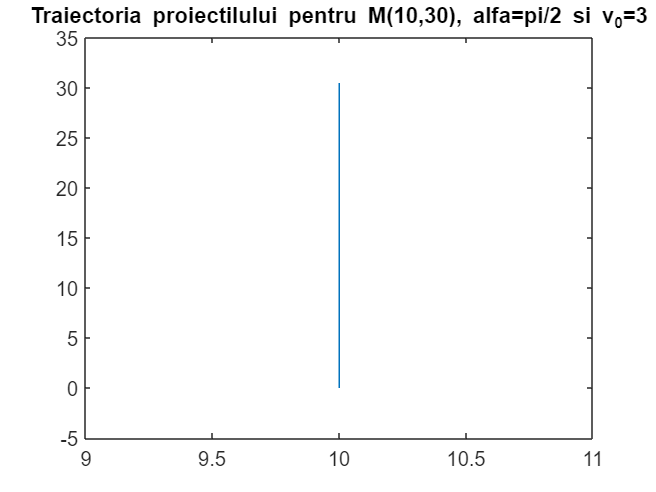

t=linspace(t_0,t_f);

plot(x(t),y(t))
title("Traiectoria proiectilului pentru M(10,30), alfa=pi/2 si v_0=3")

## Problema 3

h=40;
v_0=5;
k=0.1;
g=9.8;
tf=3;

syms x(t) y(t);

x(t)=(v_0./k).*(1-(exp(1)).^(-k.*t));
y(t)=(-g./(k.^2)).*(exp(1)).^(-k.*t)-(g./k).*t+(g./(k.^2))+h;

v_x(t)=v_0.*exp(1).^(-k.*t);
v_y(t)=(g./k).*exp(1).^(-k.*t)-(g./k);
v=sqrt(v_x.^2+v_y.^2);
eq=y(t)==0;
assume(t>0)
t_f=solve(eq);
d=x(t_f)-x_0

$$d = 40-50\,{\left(\frac{3060513257434037}{1125899906842624}\right)}^{\frac{W_{0}\left(10\,{\mathrm{e}}^{\frac{2550\,\log\left(2\right)}{49}-\frac{51\,\log\left(3060513257434037\right)}{49}}\,\left(5\,\log\left(2\right)-\frac{\log\left(3060513257434037\right)}{10}\right)\right)}{50\,\log\left(2\right)-\log\left(3060513257434037\right)}-\frac{51}{49}}$$

h_max=t_f

$$h\_max = \frac{510}{49}-\frac{10\,W_{0}\left(10\,{\mathrm{e}}^{\frac{2550\,\log\left(2\right)}{49}-\frac{51\,\log\left(3060513257434037\right)}{49}}\,\left(5\,\log\left(2\right)-\frac{\log\left(3060513257434037\right)}{10}\right)\right)}{50\,\log\left(2\right)-\log\left(3060513257434037\right)}$$

v_f=v(t_f)

$$v\_f = \begin{array}{l} \sqrt{25\,{\left(\frac{3060513257434037}{1125899906842624}\right)}^{\frac{2\,\sigma_{1}}{50\,\log\left(2\right)-\log\left(3060513257434037\right)}-\frac{102}{49}}+{\left(98\,{\left(\frac{3060513257434037}{1125899906842624}\right)}^{\frac{\sigma_{1}}{50\,\log\left(2\right)-\log\left(3060513257434037\right)}-\frac{51}{49}}-98\right)}^{2}}\\ \mathrm{where}\\ \sigma_{1}=W_{0}\left(10\,{\mathrm{e}}^{\frac{2550\,\log\left(2\right)}{49}-\frac{51\,\log\left(3060513257434037\right)}{49}}\,\left(5\,\log\left(2\right)-\frac{\log\left(3060513257434037\right)}{10}\right)\right) \end{array}$$

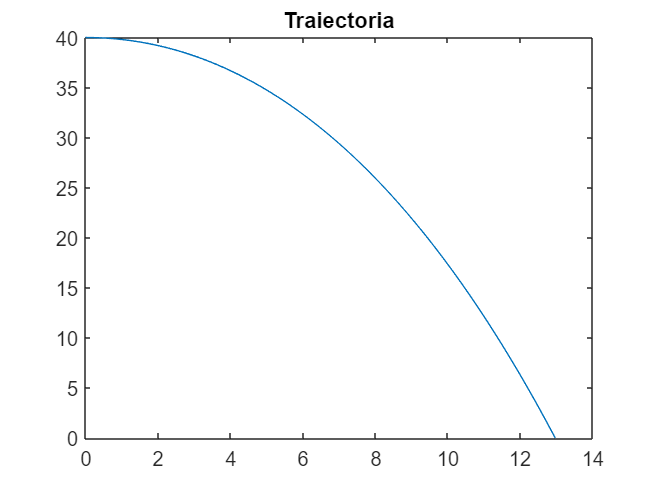

t=linspace(t_0,t_f);

plot(x(t),y(t))
title("Traiectoria")

Observ că rezultatele obținute la Problema 3 sunt aproape identice cu cele obținute la Problema 2 c). Diferența dintre cele două locuri de aterizare (și probabil a vitezei care scade mai repede în mediul natural, decât în vid) se datorează frecării cu aerul.